**Exponencial**

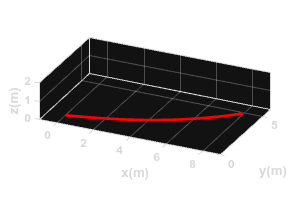

clear
close all
clc
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf = 8;             % x = [0, 8] 
ts = 0.1;
t  = 0:ts:tf;
N  = length(t);
%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
x1  = zeros(1,N+1);
y1  = zeros(1,N+1);
phi = zeros(1,N+1);
x1(1)  = 0;
y1(1)  = 1;           % y(0) = e^(0.2*0) = 1
phi(1) = atan(0.2);   % theta(0) = atan(0.2 * e^0 / 1) = atan(0.2)
%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hx = zeros(1,N+1);
hy = zeros(1,N+1);
hx(1) = x1(1);
hy(1) = y1(1);
%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u = zeros(1,N);
w = zeros(1,N);
for k = 1:N
    tk = t(k);
    % Trayectoria: y = e^(0.2*x), con x = t
    % Parametrización:
    %   x(t) = t
    %   y(t) = e^(0.2t)
    % Derivadas:
    %   dx/dt   = 1
    %   dy/dt   = 0.2  * e^(0.2t)
    %   d2y/dt2 = 0.04 * e^(0.2t)
    dx  = 1;
    dy  = 0.2  * exp(0.2*tk);
    ddy = 0.04 * exp(0.2*tk);

    % Velocidad lineal
    u(k) = sqrt(dx^2 + dy^2);

    % Velocidad angular: w = d(atan(dy/dx))/dt = ddy / (1 + dy^2)
    w(k) = ddy / (1 + dy^2);
end
%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N
    phi(k+1) = phi(k) + w(k)*ts;
    xp1 = u(k)*cos(phi(k+1));
    yp1 = u(k)*sin(phi(k+1));
    x1(k+1) = x1(k) + xp1*ts;
    y1(k+1) = y1(k) + yp1*ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([25 25]);
axis([-1 9 0 6 0 2]);  
scale = 1;
MobileRobot_5;
H1 = MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;
H2 = plot3(hx(1),hy(1),0,'r','lineWidth',2);
step = 5;
for k = 1:step:N
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2 = plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end

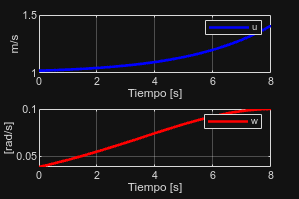

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph,'position',sizeScreen);
subplot(211)
plot(t,u,'b','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('m/s'), legend('u')
subplot(212)
plot(t,w,'r','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('w')

**Cosenoidal**

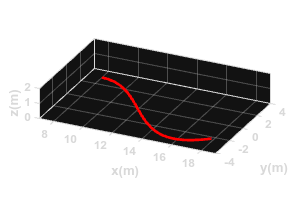

clear
close all
clc
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
t0 = 8;             % x = [8, 18] y x(t) = t
tf = 18;
ts = 0.1;
t  = t0:ts:tf;
N  = length(t);
%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Evaluadas en t = 8 (inicio real de la trayectoria)
x1  = zeros(1,N+1);
y1  = zeros(1,N+1);
phi = zeros(1,N+1);
x1(1)  = 8;                                % x(8) = 8
y1(1)  = 3*cos(0.4*(8-8));                 % = 3*cos(0) = 3
phi(1) = atan(-1.2*sin(0.4*8 - 3.2));      % = atan(0) = 0
%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hx = zeros(1,N+1);
hy = zeros(1,N+1);
hx(1) = x1(1);
hy(1) = y1(1);
%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u = zeros(1,N);
w = zeros(1,N);
for k = 1:N
    tk = t(k);
    % Trayectoria: y = 3*cos(0.4*(x-8)) = 3*cos(0.4t - 3.2), con x = t
    % Derivadas:
    %   dx/dt   = 1
    %   dy/dt   = -1.2  * sin(0.4t - 3.2)
    %   d2y/dt2 = -0.48 * cos(0.4t - 3.2)
    dx  = 1;
    dy  = -1.2 *sin(0.4*tk - 3.2);   % ¡usa tk, NO k!
    ddy = -0.48*cos(0.4*tk - 3.2);   % ¡usa tk, NO k!

    u(k) = sqrt(dx^2 + dy^2);
    w(k) = ddy / (1 + dy^2);
end
%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N
    phi(k+1) = phi(k) + w(k)*ts;
    xp1 = u(k)*cos(phi(k+1));
    yp1 = u(k)*sin(phi(k+1));
    x1(k+1) = x1(k) + xp1*ts;
    y1(k+1) = y1(k) + yp1*ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([25 25]);
axis([7 19 -4 4 0 2]);   % x va de 8 a 18, y oscila entre -3 y 3
scale = 1;
MobileRobot_5;
H1 = MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;
H2 = plot3(hx(1),hy(1),0,'r','lineWidth',2);
step = 5;
for k = 1:step:N
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2 = plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end

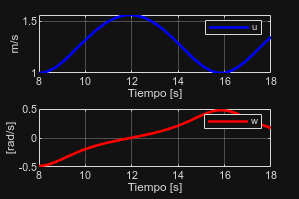

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph,'position',sizeScreen);
subplot(211)
plot(t,u,'b','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('m/s'), legend('u')
subplot(212)
plot(t,w,'r','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('w')

**Trayectoria 3**

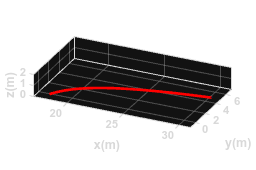

clear
close all
clc
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
t0 = 18;            % x = [18, 30] y x(t) = t
tf = 30;
ts = 0.1;
t  = t0:ts:tf;
N  = length(t);
%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Evaluadas en t = 18 
x1  = zeros(1,N+1);
y1  = zeros(1,N+1);
phi = zeros(1,N+1);
x1(1)  = 18;                       % x(18) = 18
y1(1)  = 2*log(18-17);             % = 2*ln(1) = 0
phi(1) = atan(2/(18-17));          % = atan(2)
%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hx = zeros(1,N+1);
hy = zeros(1,N+1);
hx(1) = x1(1);
hy(1) = y1(1);
%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
u = zeros(1,N);
w = zeros(1,N);
for k = 1:N
    tk = t(k);
    % Trayectoria: y = 2*ln(x-17), con x = t
    % Derivadas:
    %   dx/dt   = 1
    %   dy/dt   =  2 / (t-17)
    %   d2y/dt2 = -2 / (t-17)^2
    dx  = 1;
    dy  =  2/(tk-17);
    ddy = -2/(tk-17)^2;

    u(k) = sqrt(dx^2 + dy^2);
    w(k) = ddy / (1 + dy^2);   
end
%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for k = 1:N
    phi(k+1) = phi(k) + w(k)*ts;
    xp1 = u(k)*cos(phi(k+1));
    yp1 = u(k)*sin(phi(k+1));
    x1(k+1) = x1(k) + xp1*ts;
    y1(k+1) = y1(k) + yp1*ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([25 25]);
axis([17 31 -1 7 0 2]);   % x ∈ [18,30], y va de 0 a ~5.13
scale = 1;
MobileRobot_5;
H1 = MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;
H2 = plot3(hx(1),hy(1),0,'r','lineWidth',2);
step = 5;
for k = 1:step:N
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2 = plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end

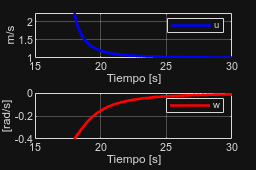

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph = figure;
set(graph,'position',sizeScreen);
subplot(211)
plot(t,u,'b','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('m/s'), legend('u')
subplot(212)
plot(t,w,'r','LineWidth',2), grid on
xlabel('Tiempo [s]'), ylabel('[rad/s]'), legend('w')